% Import data 
datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives','sub-00','sub-00_task-rest_run-01_proc-bads_ieeg.mat')
data = load(datapath)

x = data.data
x = permute(x,[2 1]);
size(x)

% Remove line noise
srate = 500;
fline = 60/srate;
nremove = 3;

figure
tic
x_filter = nt_zapline(x, fline, nremove)
toc

fline = 180/srate;
nremove = 2
figure
tic
x_filter = nt_zapline(x_filter, fline, nremove)
toc

% Save data 
data_lnrmv = y
datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives','sub-00','sub-00_task-rest_run-01_proc-lnrmv_ieeg.mat')
save(datapath, 'data_lnrmv')

% load data with lnrm
datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives', 'sub-00', 'sub-00_task-rest_run-01_proc-lnrmv_ieeg.mat');

data = load(datapath);

X = data.data_lnrmv;
fs = 500;

x = permute(X,[2 1]);
size(x)

ans =       104999         121


% Reference data
tic
[y,mn]=nt_rereference(x)

y =    -0.0002   -0.0003   -0.0003    0.0001   -0.0003   -0.0002    0.0000    0.0002    0.0000   -0.0004   -0.0002   -0.0002   -0.0001   -0.0000    0.0001    0.0002    0.0001   -0.0001   -0.0004   -0.0002   -0.0001    0.0001   -0.0002    0.0002    0.0001   -0.0001   -0.0002   -0.0004   -0.0003   -0.0001    0.0000   -0.0000    0.0001   -0.0000   -0.0002   -0.0001   -0.0001    0.0000    0.0001   -0.0002    0.0000    0.0002    0.0002   -0.0000    0.0001    0.0000   -0.0001    0.0001    0.0002    0.0003
   -0.0002   -0.0003   -0.0003    0.0001   -0.0003   -0.0002   -0.0000    0.0002    0.0000   -0.0003   -0.0002   -0.0002   -0.0001   -0.0000    0.0001    0.0002    0.0001   -0.0001   -0.0004   -0.0002   -0.0001    0.0001   -0.0002    0.0001    0.0001   -0.0001   -0.0002   -0.0004   -0.0003   -0.0001   -0.0000   -0.0000    0.0001   -0.0000   -0.0002   -0.0001   -0.0001    0.0000    0.0001   -0.0002    0.0000    0.0002    0.0002   -0.0000    0.0001   -0.0000   -0.0001    0.0001    0.0002    0

mn = 	1.0e+-3 *

   -0.0339
   -0.0353
   -0.0354
   -0.0347
   -0.0336
   -0.0329
   -0.0323
   -0.0317
   -0.0319
   -0.0315


toc 

Elapsed time is 0.575705 seconds.


Y = permute(y,[2 1]);

% Save referenced data
data_ref = Y

data_ref =    -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.00

datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives','sub-00','sub-00_task-rest_run-01_proc-ref_ieeg.mat')

datapath = '~/projects/CIFAR/data_bids/derivatives/sub-00/sub-00_task-rest_run-01_proc-ref_ieeg.mat'

save(datapath, 'data_ref')  

% Load reference data
datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives', 'sub-00', 'sub-00_task-rest_run-01_proc-ref_ieeg.mat');

data = load(datapath);

X = data.data_ref;
fs = 500;

x = permute(X,[2 1]);
size(x)

ans =       104999         121


%% Robust detrending 

% Run time ~ 30 sec
order = 10; 
w = []; 
basis= 'sinusoids';  % sinusoid seems to work better
thresh = []; 
niter = []; 
wsize = 10*500;

tic
y = nt_detrend(x,order,w,basis,thresh,niter,wsize);
toc

Elapsed time is 121.110085 seconds.



Y = permute(y, [2 1]);

## Save detrended data

data_detrend = Y

data_detrend =    -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000    

datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives','sub-00','sub-00_task-rest_run-01_proc-detrend_ieeg.mat')

datapath = '~/projects/CIFAR/data_bids/derivatives/sub-00/sub-00_task-rest_run-01_proc-detrend_ieeg.mat'

save(datapath, 'data_detrend')

% Load detrend data 

datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives', 'sub-00', 'sub-00_task-rest_run-01_proc-detrend_ieeg.mat');

data = load(datapath);

X = data.data_detrend;
fs = 500;

x = permute(X,[2 1]);
size(x)

ans =       104999         121


1, score: 0.0044423


2, score: 0.0044331


3, score: 0.004431


4, score: 0.0044313


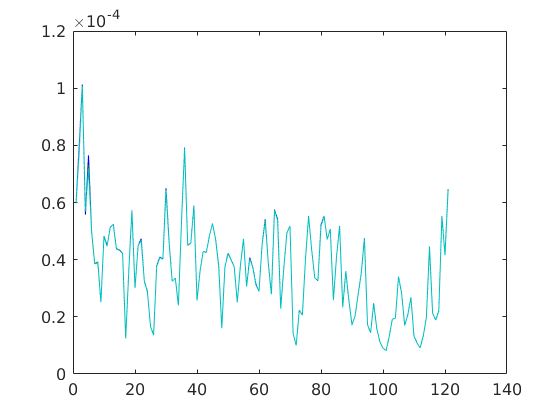

% Remove outliers

tic
w = [];
thresh = 5;
niter = 4;
[w,y] = nt_outliers(x,w,thresh,niter);

toc 

Elapsed time is 28.614017 seconds.




Y = permute(y,[2 1]);
nobs = size(Y,2);
noutl = sum(w(:)==0)*100/nobs; % Percentage of outliers

% save outlier removed data

data_outlrmv = Y

data_outlrmv =    -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000   -0.0000    0.0000    0.0000
   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -

datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives','sub-00','sub-00_task-rest_run-01_proc-outlrmv_ieeg.mat')

datapath = '~/projects/CIFAR/data_bids/derivatives/sub-00/sub-00_task-rest_run-01_proc-outlrmv_ieeg.mat'

save(datapath, 'data_outlrmv')

% Load outlier removed data 

datapath = fullfile('~','projects','CIFAR','data_bids', ... 
    'derivatives', 'sub-00', 'sub-00_task-rest_run-01_proc-outlrmv_ieeg.mat');

data = load(datapath);

X = data.data_outlrmv;
fs = 500;

x = permute(X,[2 1]);
size(x)

y =    -0.0002   -0.0003   -0.0002    0.0001   -0.0003   -0.0002    0.0001    0.0003   -0.0000   -0.0003   -0.0002   -0.0002   -0.0001   -0.0000    0.0001    0.0002    0.0001   -0.0001   -0.0003   -0.0001   -0.0002    0.0000   -0.0002    0.0002    0.0001   -0.0000   -0.0002   -0.0003   -0.0002   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000   -0.0001   -0.0000    0.0002   -0.0002    0.0000    0.0002    0.0002   -0.0001   -0.0000   -0.0000   -0.0000    0.0001    0.0002    0.0002
   -0.0002   -0.0003   -0.0002    0.0001   -0.0003   -0.0002    0.0001    0.0003   -0.0000   -0.0003   -0.0002   -0.0002   -0.0001   -0.0000    0.0001    0.0002    0.0001   -0.0001   -0.0003   -0.0002   -0.0002    0.0000   -0.0002    0.0002    0.0001   -0.0000   -0.0002   -0.0003   -0.0002   -0.0001   -0.0000    0.0000    0.0000   -0.0000   -0.0001   -0.0000   -0.0001    0.0000    0.0001   -0.0001    0.0000    0.0002    0.0002   -0.0001   -0.0000   -0.0000   -0.0000    0.0001    0.0002    0

mn = 	1.0e+-3 *

   -0.0298
   -0.0313
   -0.0313
   -0.0307
   -0.0296
   -0.0289
   -0.0283
   -0.0278
   -0.0280
   -0.0276


% Reference data

Elapsed time is 0.264425 seconds.


tic
[y,mn]=nt_rereference(x)
toc 

data_ref =    -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001
   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0003   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0002   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0001   -0.0000   -0.0000   -0.0000    0.00

datapath = '~/projects/CIFAR/data_bids/derivatives/sub-00/sub-00_task-rest_run-01_proc-ref_ieeg.mat'

Y = permute(y,[2 1]);